dataset preparation

[dataset_train,dataset_val,dataset_test] = prepdataset();

network definition and training

% DEFINE NETWORK HERE
layers = [
    sequenceInputLayer(2, MinLength=128) 

    % block one
    convolution1dLayer(3, 64, Stride=1, Padding="same")
    reluLayer
    batchNormalizationLayer
    maxPooling1dLayer(3, Stride=3)

    % block two
    convolution1dLayer(3, 64, Stride=1, Padding="same")
    reluLayer
    batchNormalizationLayer
    maxPooling1dLayer(3, Stride=3)

    % block three
    convolution1dLayer(3, 128, Stride=1, Padding="same")
    reluLayer
    batchNormalizationLayer
    maxPooling1dLayer(3, Stride=3)
    dropoutLayer(0.5)

    % block four
    convolution1dLayer(3, 128, Stride=1, Padding="same")
    reluLayer
    batchNormalizationLayer
    maxPooling1dLayer(3, Stride=3)
    dropoutLayer(0.5)

    % block five
    convolution1dLayer(3, 128, Stride=1, Padding="same")
    reluLayer
    batchNormalizationLayer
    globalAveragePooling1dLayer % instead of max pooling
    dropoutLayer(0.5)

    flattenLayer
    fullyConnectedLayer(5)
    softmaxLayer
    ];

options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    InitialLearnRate=0.001, ...
    MiniBatchSize=32, ... 
    Shuffle="every-epoch", ...
    ValidationData={dataset_val.sequences, dataset_val.labels}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

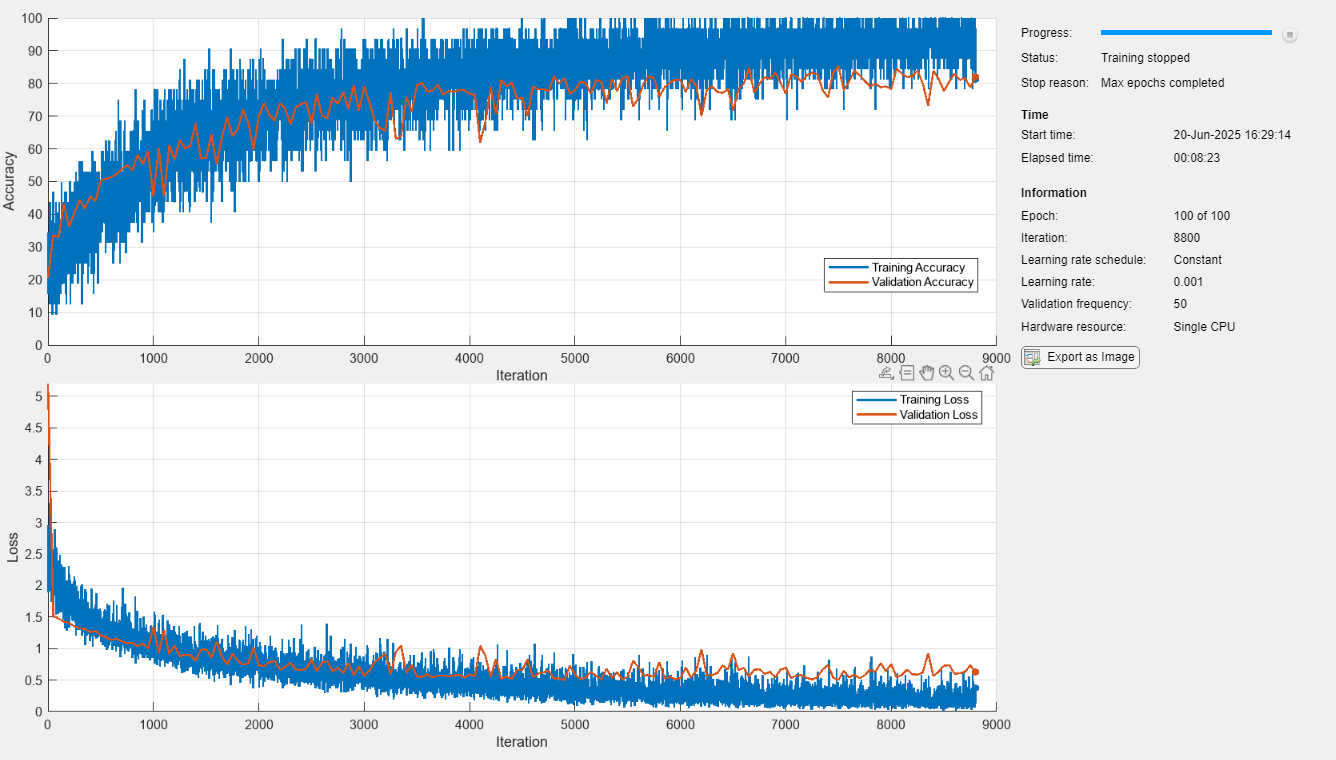

net =   dlnetwork with properties:

         Layers: [27×1 nnet.cnn.layer.Layer]
    Connections: [26×2 table]
     Learnables: [22×3 table]
          State: [10×3 table]
     InputNames: {'sequenceinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


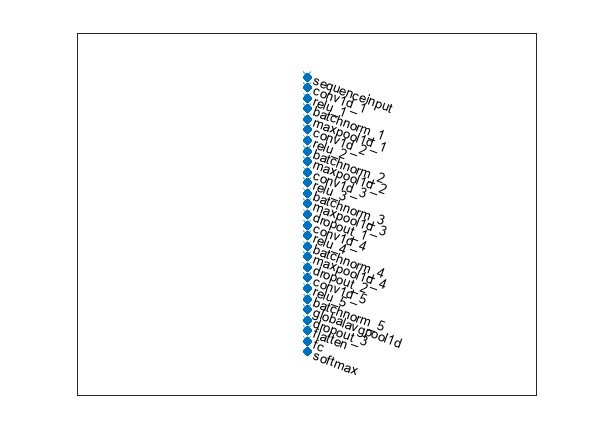

net = trainnet(dataset_train.sequences, dataset_train.labels, layers, "crossentropy", options);

evaluation

accuracy_train = eval(net, dataset_train, "ver3_accuracy_train.txt")

accuracy_train = 0.9873

accuracy_val = eval(net, dataset_val, "ver3_accuracy_val.txt")

accuracy_val = 0.8192

accuracy_test = eval(net, dataset_test, "ver3_accuracy_test.txt")

accuracy_test = 0.7841

function accuracy = eval(net, dataset, filename)
    xtestcell = dataset.sequences;
    ytest = dataset.labels;
    numsamples = numel(xtestcell);
    xtestarr = zeros(2, numsamples, 128, 'single');
    
    for i = 1:numsamples
        seq = xtestcell{i};
        xtestarr(:, i, :) = permute(single(seq), [2 3 1]);
    end
    dlxtest = dlarray(xtestarr, 'CBT');
    dlypred = predict(net, dlxtest);
    
    [~, idx] = max(extractdata(dlypred), [], 1);
    
    classes = categories(ytest);
    ypred = categorical(classes(idx), classes);

    % save to file
    log = table(ytest, ypred, 'VariableNames', ["True", "Predicted"]);
    writetable(log, filename);
    
    accuracy = mean(ypred == ytest);
end